clc
clear

syms phi s_0 s_1 mu_0 mu_1 positive
% para = [phi,s_0,s_1,mu_0,mu_1];
% assume(para,para>0&para<1,'real');
syms x_1 positive

eqn = phi/s_1*exp(-1/2*((x_1-mu_1)/s_1)^2)-(1-phi)/s_0*exp(-1/2*((x_1-mu_0)/s_0)^2) == 0;
[x_1,~,cond] = solve(eqn,x_1,"ReturnConditions",true)

$$x\_1 = \begin{array}{l} \left(\begin{array}{c} \frac{\mu_{1}\,{s_{0}}^{2}-\mu_{0}\,{s_{1}}^{2}+\sigma_{1}}{{s_{0}}^{2}-{s_{1}}^{2}}\\ -\frac{\mu_{0}\,{s_{1}}^{2}-\mu_{1}\,{s_{0}}^{2}+\sigma_{1}}{{s_{0}}^{2}-{s_{1}}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s_{0}\,s_{1}\,\sqrt{2\,{s_{0}}^{2}\,\log\left(\varphi \right)-2\,{s_{1}}^{2}\,\log\left(\varphi \right)+2\,{s_{0}}^{2}\,\log\left(s_{0}\right)-2\,{s_{1}}^{2}\,\log\left(s_{0}\right)-2\,\mu_{0}\,\mu_{1}-2\,{s_{0}}^{2}\,\log\left(s_{1}-\varphi \,s_{1}\right)+2\,{s_{1}}^{2}\,\log\left(s_{1}-\varphi \,s_{1}\right)+{\mu_{0}}^{2}+{\mu_{1}}^{2}} \end{array}$$

$$cond = \begin{array}{l} \left(\begin{array}{c} \left({s_{0}}^{2}\neq {s_{1}}^{2}\wedge 0<\sigma_{1}\wedge \sigma_{2}<0\wedge \varphi <1\right)\vee \left({s_{0}}^{2}\neq {s_{1}}^{2}\wedge 0<\sigma_{1}\wedge \neg \sigma_{2}<0\wedge \varphi <1\right)\\ \left({s_{0}}^{2}\neq {s_{1}}^{2}\wedge 0<\sigma_{1}\wedge \sigma_{2}<0\wedge \varphi <1\right)\vee \left({s_{0}}^{2}\neq {s_{1}}^{2}\wedge \neg 0<\sigma_{1}\wedge \sigma_{2}<0\wedge \varphi <1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mu_{1}\,{s_{0}}^{2}-\mu_{0}\,{s_{1}}^{2}+s_{0}\,s_{1}\,\sqrt{2\,{s_{0}}^{2}\,\log\left(\varphi \right)-2\,{s_{1}}^{2}\,\log\left(\varphi \right)+2\,{s_{0}}^{2}\,\log\left(s_{0}\right)-2\,{s_{1}}^{2}\,\log\left(s_{0}\right)-2\,\mu_{0}\,\mu_{1}-2\,{s_{0}}^{2}\,\sigma_{3}+2\,{s_{1}}^{2}\,\sigma_{3}+{\mu_{0}}^{2}+{\mu_{1}}^{2}}}{\sigma_{4}}\\ \sigma_{2}=\frac{\mu_{0}\,{s_{1}}^{2}-\mu_{1}\,{s_{0}}^{2}+s_{0}\,s_{1}\,\sqrt{2\,{s_{0}}^{2}\,\log\left(\varphi \right)-2\,{s_{1}}^{2}\,\log\left(\varphi \right)+2\,{s_{0}}^{2}\,\log\left(s_{0}\right)-2\,{s_{1}}^{2}\,\log\left(s_{0}\right)-2\,\mu_{0}\,\mu_{1}-2\,{s_{0}}^{2}\,\sigma_{3}+2\,{s_{1}}^{2}\,\sigma_{3}+{\mu_{0}}^{2}+{\mu_{1}}^{2}}}{\sigma_{4}}\\ \sigma_{3}=\log\left(s_{1}-\varphi \,s_{1}\right)\\ \sigma_{4}={s_{0}}^{2}-{s_{1}}^{2} \end{array}$$

simplify(cond)

$$ans = \begin{array}{l} \left(\begin{array}{c} {s_{0}}^{2}\neq {s_{1}}^{2}\wedge \varphi <1\wedge 0<\frac{\mu_{1}\,{s_{0}}^{2}-\mu_{0}\,{s_{1}}^{2}+\sigma_{1}}{{s_{0}}^{2}-{s_{1}}^{2}}\\ {s_{0}}^{2}\neq {s_{1}}^{2}\wedge \varphi <1\wedge \frac{\mu_{0}\,{s_{1}}^{2}-\mu_{1}\,{s_{0}}^{2}+\sigma_{1}}{{s_{0}}^{2}-{s_{1}}^{2}}<0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s_{0}\,s_{1}\,\sqrt{2\,{s_{1}}^{2}\,\log\left(-s_{1}\,\left(\varphi -1\right)\right)-2\,{s_{0}}^{2}\,\log\left(-s_{1}\,\left(\varphi -1\right)\right)-2\,\mu_{0}\,\mu_{1}+2\,\log\left(\varphi \,s_{0}\right)\,\left({s_{0}}^{2}-{s_{1}}^{2}\right)+{\mu_{0}}^{2}+{\mu_{1}}^{2}} \end{array}$$

simplify(x_1)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\mu_{1}\,{s_{0}}^{2}-\mu_{0}\,{s_{1}}^{2}+\sigma_{1}}{{s_{0}}^{2}-{s_{1}}^{2}}\\ -\frac{\mu_{0}\,{s_{1}}^{2}-\mu_{1}\,{s_{0}}^{2}+\sigma_{1}}{{s_{0}}^{2}-{s_{1}}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s_{0}\,s_{1}\,\sqrt{2\,{s_{1}}^{2}\,\log\left(-s_{1}\,\left(\varphi -1\right)\right)-2\,{s_{0}}^{2}\,\log\left(-s_{1}\,\left(\varphi -1\right)\right)-2\,\mu_{0}\,\mu_{1}+2\,\log\left(\varphi \,s_{0}\right)\,\left({s_{0}}^{2}-{s_{1}}^{2}\right)+{\mu_{0}}^{2}+{\mu_{1}}^{2}} \end{array}$$

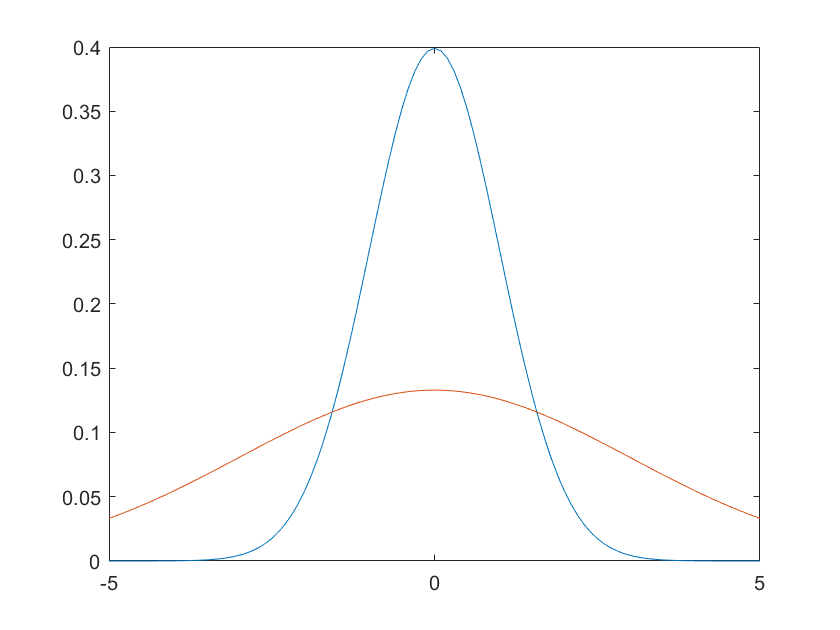

x = [-5:.1:5];
y1 = normpdf(x,0,1);
y2 = normpdf(x,0,3);
plot(x,y1,x,y2)

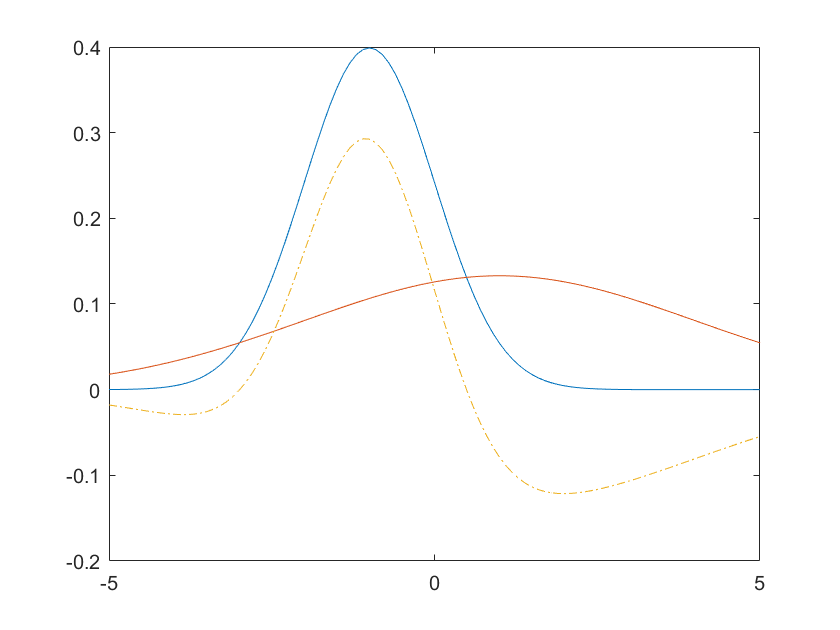

x = [-5:.1:5];
y1 = normpdf(x,-1,1);
y2 = normpdf(x,1,3);
plot(x,y1,x,y2,x,y1-y2,'-.')